% Specify the file path
RAW_RESULTS_DIR = "..\7 - Results\2 - Raw Test Images\";
EX_NAME = "vo5_spray_dry_22cm_fast";
EX_DIR = RAW_RESULTS_DIR + EX_NAME

EX_DIR = "..\7 - Results\2 - Raw Test Images\vo5_spray_dry_22cm_fast"

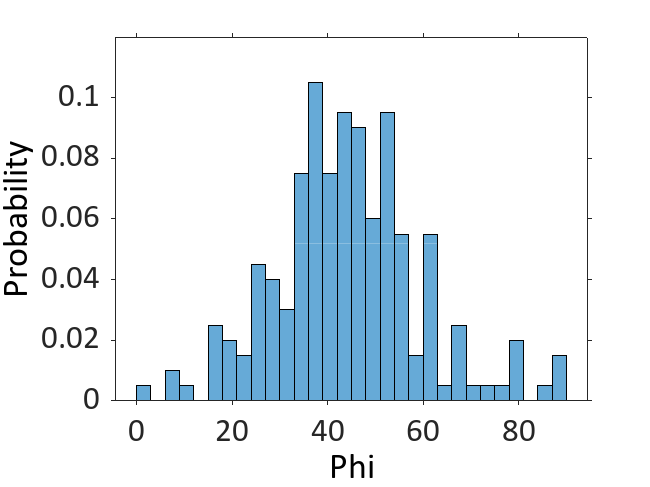


fid = fopen(EX_DIR + "\0 - analysis.txt", 'r');
for i = 1:6
    fgetl(fid);
end
data_cell = cell(0);
while ~feof(fid)
    line = fgetl(fid);
    if ~ischar(line)
        disp("ree");
        break;
    end
    data_cell = [data_cell; strsplit(line, ',')];
end
data = str2double(data_cell);
data = data(:,1:7);
fclose(fid);

for i = 1:length(data)
    if data(i,7) < 0
      temp = data(i, 5);
      data(i, 5) = data(i, 6);
      data(i, 6) = temp;
      data(i, 7) = data(i, 7) + 90;
    end
end

LABELS = ["n", "Time", "centroid X position", "cetroid Y position", "beam X radius", "beam Y radius", "Phi"];
for i = 3:7
    histogram(data(:,i), 30, 'Normalization','probability')
    set(gca,'TickDir','out'); % The only other option is 'in'
    xlabel(LABELS(i), 'Color', [0 0 0])
    ylabel("Probability", 'Color', [0 0 0])
    set(gca,'FontName','Calibri','FontSize',20);
    saveas(gcf,EX_DIR + '\0 - ' + LABELS(i) + '_hist.png')


end